# 1). 2p imaging processing pipeline

## 1. Set the global variable strDir_CaRMA_Wiki

*Please change the strDir_CaRMA_Wiki variable to your own path of CaRMA Wiki in initDir_CaRMA_Wiki.m file*

initDir_CaRMA_Wiki();

## 2. Split the volumetric images recorded by Scanimage into images of individual imaging planes. Details are in Batch_SplitImages_SI_FastZ.m.

- Batch_SplitImages_SI_FastZ.m processes the ScanImage files in a batch.

- For each image file, the script creates a subfolder containing all splitted images of individual imaging plane. The splitted images are used for image registration to correct the image motion. Please keep the subfolder organization for further processing.

- The script generates an average intensity projection image for each imaging plane, whose name is ended with "_Avg.tif". These average images are used as the first round of image template in image registration.

- To make it easy to examine the images in FiJi, the script finally combines the splitted images into a big file so that all imaging planes can be exmamined simultaneously in FiJi.

- The script also saved the meta information of each image to a .mat file.

**    Note1 :  The script uses modified (fix some bugs) opentif function from ScanImage 2016b (**[Vidrio Technologies](http://scanimage.vidriotechnologies.com/display/SI2016/Open+Tiff)**) to read ScanImage files. It needs their permission for redistribution. **

**    Note2: After submitting our manuscripts, I found opentif function became quite slow in Matlab 2019 and later, because setDirectory function becomes quite slow in those versions of Matlab. Thus, I further modified the opentif function to make it faster. In additon, I wrote openSITif interface function to use ScanImageTiffReader (**[https://vidriotech.gitlab.io/scanimagetiffreader-matlab/](https://vidriotech.gitlab.io/scanimagetiffreader-matlab/)**) to read the ScanImage image data. Because I used the opentif function in my analysis pipeline,the default method in the script is opentif. However, ScanImageTiffReader method is much faster, if you want to use ScanImageTiffReader method, you can change the code on ****line 23**** in SplitImages_SI_FastZ.m (**`[Header,Aout,imgInfo] = openSITif(strFn); -> [Header,Aout,imgInfo] = openSITif(strFn, false);`**)**

Batch_SplitImages_SI_FastZ

For the example data, the following gray subfolders and files are generated by the script.

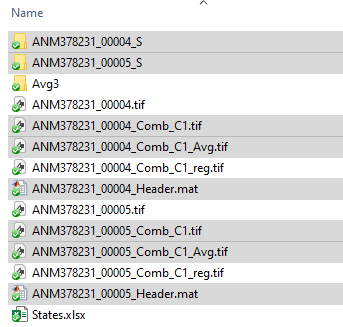 

The splitted files in ANM378231_00004_S are shown below.

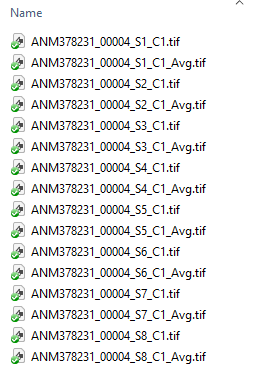

## 3. Register the splitted images in each imaging planes across time to correct the motion artifacts. 

- To speed up the process, the script was run in **Janelia Computer Cluster** in parallel.** Please adapt the codes to your own computing environment**. The script also uses Matlab **Parallel Computing Toolbox** to accelerate the computation. If you don't have **Parallel Computing Toolbox**, please change **parfor **to** for** in the script.

- The script registers images acquired from one animal on one day in batch process mode.

- The registration is restricted within one imaging plane.

- To batch process images acquired from multiple animal or on different days, please change the parameters (`clImgDirs, clTrials_GenRefGrp, clTrial_Refs, clTrials_UseRefGrp`) in the second cell. Details about these parameters are in MatlabCmd_2p_FastZ_Vol_Day_par.m

- The script first registers the images acquired in the trials assigned by `clTrials_GenRefGrp` and iterately generates sharp reference images that can be used to register the images acquired in other trials. Then, it registers images from other trials to the reference images assigned by `clTrial_Refs.`

    **Note: Because the script uses Linux shell script to perform the registration, to avoid unexpected error, ****do not include space in the name of your folders****.**

MatlabCmd_2p_FastZ_Vol_Day_par

For the example data with the parameters in above script (using ANM378231_00004.tif as reference),** for each imaging plane**, the following gray files are generated in the subfolder containing the splitted reference images by the script.

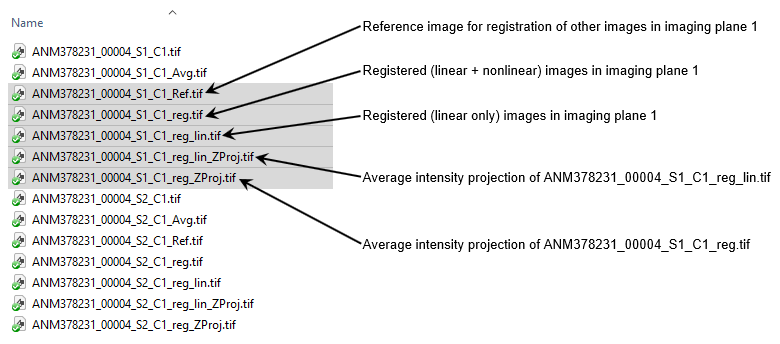

For other images (such as ANM378231_00005.tif in the example data), the script generates following gray files **for each imaging plane**.

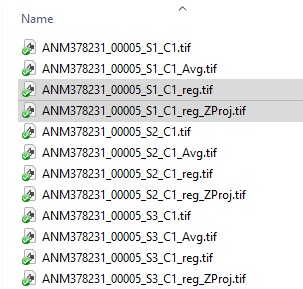

## 4. (*Option*) Combine the registered images of individual imaging planes into a big image file  so that it can be easily examined simultaneously in FiJi.

     Please set the parameters in the second cell. These parameters depend on the starage organization of your data. So, **please organize your data in a consistent storage structure.**

Batch_Comb_RegImgs_From_Sub

For the example data with the parameters in the script above,** for each imaging plane**, the following gray files combining the registered images are generated by the script.

   ** Note1: I left these combined registered images in the example data folder to show registration performance.**

**    Note2: I also put the behavior videos in Fear_Imaging_Exp\Behavior_Video subfolder so that the combined registered images can be further combined with behavior videos to show the neuronal responses to behaviors.**

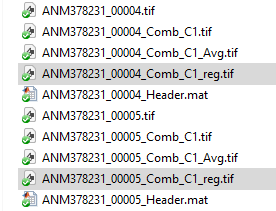

## 5. For each imaging plane, we use FiJi to concatenate the registered images across all trials on one day

- The following script generates a concatenation list as input of the FiJi script in next step.   

CatListGen_2p

The script generates a CatList.log file and a empty subfolder Reg_Cat, as highligted in gray below. Both of them are used in the next step.

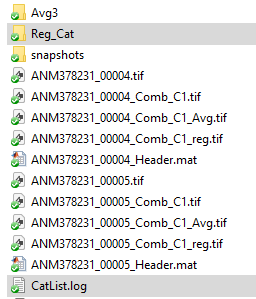

        2.  Run** Cat_Exp.ijm** Macro script in FiJi. I did not put these 2 steps in one Matlab script, because (a) the processing is much faster in FiJi; (b) I always check the registration results in FiJi before further analyses. Following shows the concatenated images in Reg_Cat subfoler.

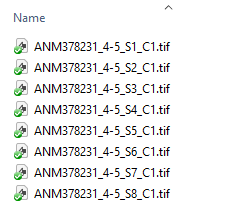

        3. (***Option***) To improve the signal-noise ratio, I temporally downsampled the images by averaging 3 frames into 1 frame. The downsampled images in **Avg3 **subfolder for further analyses are highlighted in gray below.

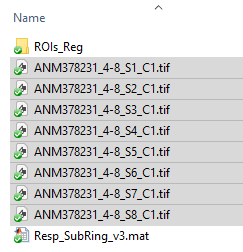

           ** Note1. If you'd like to temporally downsample your images, to avoid averaging across trials, please make sure the total frame number in one trial is divisible by the bin size. For example, 1350/3 = 450 in my case.**

**            Note2. For the downsampled images, I concatenated all images from all trials on that day (trial 4 to 8, but not only trial 4 and 5).**

## 6. After *ex vivo -> in vivo* registration (details in *ExVivo_InVivo_Reg.mlx*), we can get ROIs for individual identified neurons in ROIs_Reg subfolder as shown below.

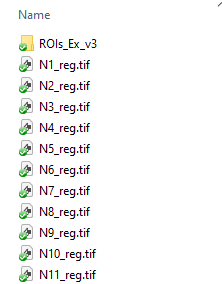

## 7. Extract calcium dynamic responses from images

- Batch_ExtractVolResp_SubRing_v3.m extract calcium signals in batch process mode

- For each neuron, the script generates a exclusive volumetric ROI mask and a volumetric ring-shape background mask in  ROIs_Ex_v3 subfolder

- For each neuron, the script measures its calcium signal by average intensity in ROI mask - average intensity in background mask.

- It saves the extracted calcium signals of all identified neurons in Resp_SubRing_v3.mat file. 

Batch_ExtractVolResp_SubRing_v3